# Cosmology Calculations

The script has a function for each plot. This way toggling the plots on/off is easy. The script is done with Matlab version 2020a, which supports functions inside scripts, thus with older versions each function must be separated to Matlab function files. The script part is first and all the functions are declared afterwards.

The functions have similar commands, so some of the code further down is not commented as well as the code above it.

## Calculation Parameters and Global Variables

Here we declare global variables, First is Hubble constant, with correction factor, in unit (10 Gyr)^-1.

global H_T; H_T = 0.6715 * 1.0226;

Precision value: smaller gives more precise result. This single value affects various tolerance values in different algorithms.

global a0; a0 = 10^-3;

Maximum t-value for differential equation solver, in giga years and starting from the big bang. In some cases it is wanted that the solver is terminated after point $a(T) = 1$ is reached. This is the limit, if we don't want to stop the solver at this point.

global t_end; t_end = 69;

Parameters for the models. $\Omega^{\Lambda}$ for the $\Lambda R$-model is solved from equation $\Omega^{B} + \Omega^{\Lambda} + \Omega^{\Lambda R}_T = 1$. Function for `solve_omegaL` is provided later.

global F_omegaB;  F_omegaB  = 0.049;
global F_omegaD;  F_omegaD  = 0.268;
global F_omegaL;  F_omegaL  = 0.683;
global LR_omegaB; LR_omegaB = F_omegaB;
global LR_omegaL; LR_omegaL = solve_omegaL(LR_omegaB,1);

Parameters at which $\Omega^{\Lambda R}_T$ is maximised.

global omega_LR_opt
global omega_B_opt
global omega_L_opt

[omega_LR_opt, omega_B_opt, omega_L_opt] = solve_optimum();
%disp(legend_text('Optimal parameters', omega_LR_opt, NaN, omega_B_opt, omega_L_opt, NaN, NaN))

Some plot related variables.

% Colors
global blue;  blue  = [ 50, 110, 230]/255;
global red;   red   = [250,  42,  30]/255;
global green; green = [ 24, 185,  50]/255;

% Line width in plots
global lineWidth; lineWidth = 1;

## Calling the Plotting Functions

Here you can select which Figures you want to plot. Comment out the ones that you don't want to plot.

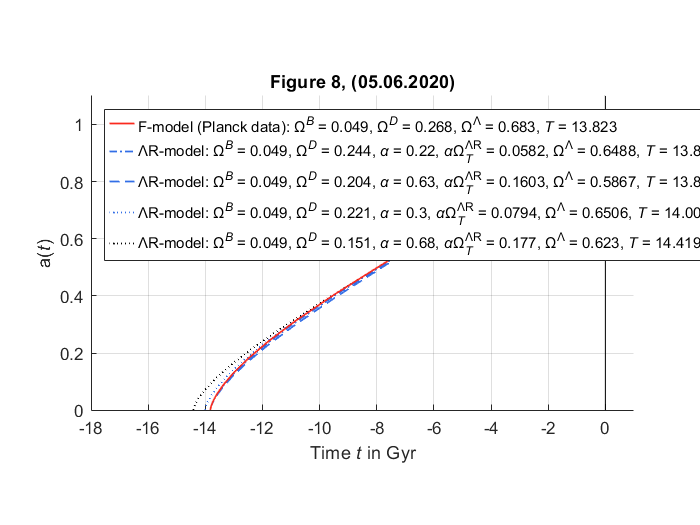

%[a_res, t_res, omega_LR] = LR_model(1,0, 1,true);
%disp(-t_res(1) - 9.70860731629968)

% Figure 1 / Fig 1
%final_plot_1()

% Figure 2 / Fig 3
%final_plot_50()

% Figure 3 / Fig 4
%final_plot_3()

% Figure 4 / Fig 5-7
%final_plot_4()

% Figure 5 / Fig 8-16
%final_plot_many_B()

% Figure 6 / 19 yhtälö 25
%[omegaB, omegaLR, omegaL, T, omegaLR_lin, omegaL_lin] = final_plot_RB();
%print_table_two_col([omegaB,omegaLR,omegaL,T], [4 4 4 3])
%print_table_two_col([omegaB, omegaLR_lin, omegaL_lin], [4 4 4])

% Figure 8
figure_8()

%figure_9()

## Differential Equation Solvers

Let's start with equations


$$\left( \frac{\dot{a}}{a} \right) = \frac{H_T^2}{a^3} \Omega^{B+D} +  \frac{H_T^2}{a^3} \alpha \Omega^{\Lambda R} + H_T^2 \Omega^{\Lambda},$$
            
$$\Omega^{\Lambda R}_t = \frac{H_T \sqrt{\Omega^{\Lambda}}}{a(t)} \int_0^t a(s) \cdot e^{-s \cdot H_T \sqrt{\Omega^{\Lambda}}} \text{d}s.$$


Let's subsitute $\Omega^{\Lambda R}_t$. Let's define $b$, such that,


$$\Omega^{\Lambda R}_t = \frac{H_T \sqrt{\Omega^{\Lambda}}}{a} b.$$


Now we have


$$\left( \frac{\dot{a}}{a} \right) = \frac{H_T^2}{a^3} \Omega^{B+D} +  \frac{\alpha H_T^3 \sqrt{\Omega^{\Lambda}}}{a^4}  b + H_T^2 \Omega^{\Lambda},$$
            
$$\dot{b} = a \cdot e^{-t \cdot H_T \sqrt{\Omega^{\Lambda}}},$$


and solving for $\dot{a}$ gives,

$\dot{a} = H_T \sqrt{\frac{\Omega^{B+D}}{a} + \frac{\alpha H_T \sqrt{\Omega^{\Lambda}}}{a^2} b + a^2 \Omega^{\Lambda}}$,            $\dot{b} = a \cdot e^{-t \cdot H_T \sqrt{\Omega^{\Lambda}}}.$

After finding a numerical solution, we can evaluate $\Omega^{\Lambda R}_t$ by


$$\Omega^{\Lambda R}_t = \frac{H_T \sqrt{\Omega^{\Lambda}}}{a} b.$$


We solve the equations with time unit 10 Gyrs, and the unit conversion to Gyrs is done after that in the differential equation solver.

function [a_res, t_res, omega_LR] = LR_model(omegaBD, omegaL, alpha, terminate_T, max)
    % Load global variables
    global H_T t_end a0;
    
    [a_res,b_res,t_res] = runge_kutta(@(t, a, b)H_T * sqrt(omegaBD/a + alpha*H_T*sqrt(omegaL)/a^2*b + a^2*omegaL), ...
                                      @(t, a, b)a * exp(-t * H_T * sqrt(omegaL)), ...
                                      a0, ...
                                      t_end/10, a0/10, terminate_T, max);
                                  
    omega_LR = H_T .* sqrt(omegaL) ./ a_res .* b_res;
end

The Friedmann model's equations are solved similarly as above, resulting to,

$\dot{a} = H_T \sqrt{\frac{\Omega^{B+D}}{a} + a^2 \Omega^{\Lambda}}$,            $\dot{b} = a \cdot e^{-t \cdot H_T \sqrt{\Omega^{\Lambda}}}$.

function [a_res, t_res, omega_LR] = F_model(omegaBD, omegaL, terminate_T, max)
    % Load global variables
    global H_T t_end a0;
    
    [a_res,b_res,t_res] = runge_kutta(@(t, a, b)H_T * sqrt(omegaBD/a + a^2*omegaL), ...
                                      @(t, a, b)a * exp(-t * H_T * sqrt(omegaL)), ...
                                      a0, ...
                                      t_end/10, a0/10, terminate_T, max);
                                  
    omega_LR = H_T .* sqrt(omegaL) ./ a_res .* b_res;
end

Simple function that returns $\Omega^{\Lambda R}_T$. This function is useful with solvers furher down.

function omegaLR_T = LR_model_omegaLR_T(omegaB,omegaL,alpha)
    [~, ~, omega_LR] = LR_model(omegaB, omegaL, alpha, true, false);
    omegaLR_T = omega_LR(end);
end

## Other Equation Solver Functions

Solves $\Omega^{\Lambda}$ from the flatness algorithm $\Omega^B + \Omega^{\Lambda} + \Omega^{\Lambda R}_T = 1$.

function omegaL = solve_omegaL(omegaB, alpha)
    % Set solving accuracy with a0
    global a0
    options = optimset('TolFun',a0);
    
    omegaL = fzero(@(omegaL) alpha*LR_model_omegaLR_T(omegaB, omegaL, alpha) + omegaB + omegaL - 1, ...
                    (1-omegaB)^1.6,... % initial guess
                    options);
end

Same as above, except $a$ is approximated with $a = H_T t$. No integration is needed in this algorithm.

function omegaL = solve_omegaL_linear(omegaB)
    % Set solving accuracy with a0
    global a0
    options = optimset('TolFun',a0);
    if omegaB == 1
        omegaL = 0;
    else
        omegaL = fzero(@(omegaL)real(omegaB + (1-exp(-sqrt(omegaL))*(1+sqrt(omegaL)))/sqrt(omegaL) + omegaL) - 1, ...
                        0.7*(1-omegaB), ... % initial guess
                        options);
    end
end

Solves $\alpha$ from flatness equation, $\Omega^B + \Omega^{\Lambda} + \alpha \Omega^{\Lambda R}_T  + \Omega^D = 1$.

function alpha = solve_alpha(omegaB, omegaD, omegaL)
    % Set solving accuracy with a0
    global a0
    options = optimset('TolFun',a0);
    
    alpha = fzero(@(alpha)omegaB + omegaD + omegaL + alpha*LR_model_omegaLR_T(omegaB + omegaD, omegaL, alpha) - 1, ...
                    0.5, ... % initial guess
                    options);
end

Solver for optimum $\max_{\Omega^B}{\Omega^{\Lambda R}_T}$.  $\Omega^{\Lambda}$ is solved from the flatness equation, $\Omega^B + \Omega^{\Lambda} + \Omega^{\Lambda R}_T = 1$. In the function we solve $\min_{\Omega^B}{(-\Omega^{\Lambda R}_T)}$

function [omegaLR, omegaB, omegaL] = solve_optimum()
    % Set solving accuracy with a0
    global a0
    options = optimoptions(@fminunc, 'OptimalityTolerance', a0, 'Display', 'off');
    
    [omegaB, omegaLRneg] = fminunc(@(omegaB)-LR_model_omegaLR_T(omegaB, solve_omegaL(omegaB,1), 1), ...
                                    0.0458, ... % initial guess
                                    options);
    
    omegaLR = -omegaLRneg;
    omegaL = 1 - omegaB - omegaLR;
end

## Tools for plotting

This section contains some general functions for plotting.

Rounds number x to n significant digits. Returns the number in a string format.

function res = print_num(x, n)
    %res = num2str(round(x,n,'significant'));
    res = num2str(round(x,n));
end

% Saves current plot to current directory. This function adds grid.
% leg is legend object.

Saves current plot to current directory. This function adds grid and shortens the legend's line samples. Variable `size` modifies text size. Smaller value corresponds to a bigger font size.

function save_plot(name, leg)
    size = 3.5;
    grid on
    if ~isa(leg, 'double')
        leg.ItemTokenSize = [15,9]; % default [30,18]
    end
    set(gcf, 'Units', 'inches');
    screenposition = get(gcf, 'Position');
    set(gcf,...
        'PaperPosition', [0 0 size*screenposition(3:4)],...
        'PaperSize', size*screenposition(3:4));
    print(name, '-dpdf', '-fillpage')
end

Creates texts for legends. Input values `NaN`, are not printed.

function res = legend_text(name,R,T,B,D,alpha,L,BDFormat,alphaLRFormat)
    res = [name ': '];
    if ~isnan(R) &&  (alphaLRFormat == "R"|| alphaLRFormat == "R,aR" || alphaLRFormat == "a,R" || alphaLRFormat == "a,R,aR")
        res = [res 'Ω^{ΛR}_{\itT} = ' print_num(R,4) ', '];
    end
    if ~isnan(B) && (BDFormat == "B"|| BDFormat == "B,D" || BDFormat == "B,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{\itB} = ' print_num(B,4) ', '];
    end
    if ~isnan(D) && (BDFormat == "D"|| BDFormat == "B,D" || BDFormat == "D,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{\itD} = ' print_num(D,4) ', '];
    end
    if ~isnan(B) && ~isnan(D) && (BDFormat == "BD"|| BDFormat == "B,BD" || BDFormat == "D,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{{\itB}+{\itD}} = ' print_num(B+D,4) ', '];
    end
    if ~isnan(alpha) && (alphaLRFormat == "a"|| alphaLRFormat == "a,aR" || alphaLRFormat == "a,R" || alphaLRFormat == "a,R,aR")
        res = [res '{\itα} = ' print_num(alpha,4) ', '];
    end
    if ~isnan(alpha) && ~isnan(R) && (alphaLRFormat == "aR"|| alphaLRFormat == "a,aR" || alphaLRFormat == "R,aR" || alphaLRFormat == "a,R,aR")
        res = [res '{\itα}Ω^{ΛR}_{\itT} = ' print_num(alpha*R,4) ', '];
    end
    if ~isnan(L)
        res = [res 'Ω^Λ = ' print_num(L,4) ', '];
    end
    if ~isnan(T)
        res = [res '{\itT} = ' print_num(T,3) ', '];
    end
    res = res(1:end-2); % removes last ', '
end

Plots vertical line $x=0$ on to the plot.

function draw_y_axis()
    hold on
    plot([0 0], ylim, '-k', 'LineWidth',0.5,'HandleVisibility','off')
    hold off
end

Returns current date

function today = print_today()
    formatOut = '(dd.mm.yyyy)';
    today = datestr(datetime('now'),formatOut);
end

Prints a two-column table in LaTeX table -format. All data must be numeric. Precision is specified to each column of `matrix`.

function print_table_two_col(matrix, precision)
    et = char(ones(length(matrix(:,1)),1) * ' & ');
    res = char(ones(length(matrix(:,1)),1) * ' ');
    
    for p = 1:(length(matrix(1,:))-1)
        res = [res, print_num(matrix(:,p), precision(p)), et];
    end
    
    % The last column without ' & ' at the end
    res = [res, print_num(matrix(:,end), precision(end))];
    lines = ceil(length(matrix(:,1))/2);
    
    % If we have uneven number of rows, we need to add a blank row to the end
    if mod(length(matrix(:,1)),2) == 1
        blanks = char(ones(1,length(res(1,:))) * ' ');
    else
        blanks = [];
    end
    
    line = char(ones(lines,1) * ' \\');
    et = char(ones(lines,1) * ' &');
    
    disp([res(1:lines,:), et, [res(lines+1:end,:); blanks], line])
end

## Figure 1

Plot showing scale factor $a(t)$ of the Friedmann model and $\Lambda R$-model. Plot shows $t \leq T$.

function final_plot_1()
    % Create new figure frame
    figure; hold on;
    
    % Load global variables
    global F_omegaB F_omegaD F_omegaL
    global LR_omegaB LR_omegaL
    global red blue lineWidth
    
    % We only need to plot functions until a(T) = 1,
    % so we stop the differential equation solver at that point
    terminate_T = true;
    findMax = false;
    
    % ΛR-model alpha = 1
    alpha = 1;
    
    % Run the Friedmann model
    [aH, tH, omega_LRH] = F_model(F_omegaB + F_omegaD, F_omegaL, terminate_T, findMax);
    pH = plot(tH, aH, '-', 'LineWidth', lineWidth, 'Color', red);
    
    F0_omegaL = 0.8;
    F0_omegaBD = 0.2;
    % Run the Friedmann model
    [a0, t0, omega_LR0] = F_model(F0_omegaBD, F0_omegaL, terminate_T, findMax);
    p0 = plot(t0, a0, '--', 'LineWidth', lineWidth, 'Color', 'k');
    
    % Run the ΛR-model
    [a1, t1, omega_LR1] = LR_model(LR_omegaB, LR_omegaL, alpha, terminate_T, findMax);
    p1 = plot(t1, a1, '-.', 'LineWidth', lineWidth, 'Color', blue);
    
    % Set plot legend
    leg = legend([pH p0 p1],...
        {legend_text('F-model (Planck data)',  omega_LRH(end), -tH(1), F_omegaB,  F_omegaD, NaN, F_omegaL, 'B,D', ''), ...
         legend_text('F-model',  omega_LR0(end), -t0(1), F_omegaB,  F0_omegaBD - F_omegaB, NaN, F0_omegaL, 'BD', ''), ...
         legend_text('ΛR-model', omega_LR1(end), -t1(1), LR_omegaB, NaN,      NaN, LR_omegaL, 'B', '')},...
        'Location',...
        'northwest');
    
    % Set title etc., and save the figure
    title(['Figure 1 ', print_today()])
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    axis([-18 1 0 1.1])
    daspect([1 0.1 1])
    draw_y_axis()
    save_plot('kuva_1', leg)
end

## Figure 2

function final_plot_50()
    figure; hold on;
    
    global H_T
    global F_omegaB F_omegaD F_omegaL
    global LR_omegaB LR_omegaL
    global red blue lineWidth
    
    % Create t-axis points for f and g
    t = linspace(0,51,200);
    
    % Plot f
    pf = plot(t, exp(t/10 * H_T), ':', 'LineWidth', lineWidth, 'Color', 'k');
    % Plot g
    pg = plot(t, exp(t/10 * H_T * sqrt(LR_omegaL)), ':', 'LineWidth', lineWidth, 'Color', 'k');
    

    
    % ΛR-model alpha = 1
    alpha = 1;
    findMax = false;
    
    % F-model
    [a0, t0, ~] = F_model(F_omegaB + F_omegaD, F_omegaL, false, findMax);
    p0 = plot(t0, a0, '-', 'LineWidth', lineWidth, 'Color', red);
    
    % ΛR-model
    [a1, t1, ~] = LR_model(LR_omegaB, LR_omegaL, alpha, false, findMax);
    p1 = plot(t1, a1, '-.', 'LineWidth', lineWidth, 'Color', blue);
    
    % Add legend to the plot
    leg = legend([p0 p1],...
        {legend_text('F-model', NaN,-t0(1),F_omegaB,F_omegaD,NaN,F_omegaL, 'BD', '') ...
         legend_text('ΛR-model',NaN,-t1(1),LR_omegaB, NaN,NaN, LR_omegaL, 'B' , '')},...
        'Location',...
        'northwest');
    
    tPoint = 33;
    drawPointer('{\itf}({\itt}) ',[tPoint,27],[exp(tPoint/10 * H_T),11],[0,0],'right','k')
    tPoint = 36;
    drawPointer(' {\itg}({\itt})',[tPoint,41],[exp(tPoint/10 * H_T * sqrt(LR_omegaL)),7],[0,0],'left','k')
    
    % Add title etc. and save the plot
    title(['Figure 2 ', print_today()])
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    draw_y_axis()
    axis([-20 50 0 20])
    save_plot('kuva_2', leg)
end

## Figure 3

function final_plot_3()
    figure; hold on;
    
    global F_omegaB F_omegaD F_omegaL
    global LR_omegaB LR_omegaL
    global red blue lineWidth
    
    % Go pass the point a(T) == 1
    terminate_T = false;
    
    % Friedmann
    D0 = 1-LR_omegaL-F_omegaB;
    [~,t0,omega_LR0] = F_model(F_omegaB + D0, LR_omegaL, terminate_T, true);
    p0 = plot(t0, omega_LR0, '-', 'Color', red, 'LineWidth', lineWidth);
    
    % ΛR-model alpha = 1
    alpha = 1;
    
    % ΛR-model
    [~, t1, omega_LR1] = LR_model(LR_omegaB, LR_omegaL, alpha, terminate_T, true);
    p1 = plot(t1, omega_LR1, '-.', 'Color', blue, 'LineWidth', lineWidth);
    
    [F_max_omega_LR, ind0] = max(omega_LR0);
    [LR_max_omega_LR, ind1] = max(omega_LR1);
    
    F_max_t = t0(ind0);
    LR_max_t = t1(ind1);
    
    disp(F_max_t)
    disp(LR_max_t)
    
    drawPointer(print_num(F_max_omega_LR,4),[F_max_t, 30.3],[F_max_omega_LR,F_max_omega_LR],[0,0],'left',red)
    drawPointer(print_num(LR_max_omega_LR,4),[LR_max_t, 30.3],[LR_max_omega_LR,LR_max_omega_LR],[0,0],'left',blue)
    
    drawPointer(print_num(F_max_t,4),[F_max_t, F_max_t],[F_max_omega_LR,0.11],[0,-0.006],'left',red)
    drawPointer(print_num(LR_max_t,4),[LR_max_t, LR_max_t],[LR_max_omega_LR,0.094],[0,-0.006],'left',blue)
    
    leg = legend([p0, p1],...
            {legend_text('Ω^{ΛR}(t) along F-model trajectory', NaN, NaN, F_omegaB,  F_omegaD, NaN, LR_omegaL, '', '') ...
             legend_text('Ω^{ΛR}(t)',NaN, NaN, LR_omegaB, NaN, NaN, LR_omegaL, '', '')},...
             'Location',...
             'southeast');
    
    % Separation of the omegaLR_T texts
    textOffset = 0.003;
    
    [~, F_xAxisIntersect] = min(abs(t0));
    [~, LR_xAxisIntersect] = min(abs(t1));
    
    % Solve for the omegaLR_T and draw the values on the plot
    %[~,~,omegaLR] = LR_model(LR_omegaB, LR_omegaL, 1, true, false);
    draw_x_value('', omega_LR1(LR_xAxisIntersect), -12, 0, blue,-textOffset)
    %[~,~,omegaLR] = F_model(F_omegaB + F_omegaD, F_omegaL, true, false);
    draw_x_value('', omega_LR0(F_xAxisIntersect), -12, 0, red, textOffset)
    
    
    % Set title etc. and save the figure
    title(['Figure 3 ', print_today()])
    xlabel('Time {\itt} in Gyr'); ylabel('Ω^{ΛR}({\itt})')
    axis([-20 50 0 0.3])
    draw_y_axis()
    save_plot('kuva_3', leg)
end

function draw_x_value(name,value,xmin,xIntersect,color,offset)
    hold on
    plot([xmin,xIntersect],[value value], 'Color', color, 'LineWidth',0.5,'HandleVisibility','off')
    if name == ""
        t = text(xmin,value+offset,[print_num(value,4), ' '],'HorizontalAlignment','right','Rotation',0,'FontSize',9);
    else
        t = text(xmin,value+offset,[name, ' = ', print_num(value,4), ' '],'HorizontalAlignment','right','Rotation',0,'FontSize',9);
    end
    t.Color = color;
    hold off
end

function drawPointer(name,x,y,textOffset,textPos,color)
    hold on
    plot(x,y, 'Color', color, 'LineWidth',0.5,'HandleVisibility','off')
    t = text(x(2)+textOffset(1),y(2)+textOffset(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',9);
    t.Color = color;
    hold off
end

## Figure 4

function final_plot_4()
    figure; hold on;
    
    global F_omegaB
    global LR_omegaB LR_omegaL
    global omega_LR_opt
    global blue lineWidth
    
    findMax = false;
    
    % ΛR-model
    D1 = 0.2 - LR_omegaB;
    alpha1 = solve_alpha(LR_omegaB, D1, LR_omegaL);
    [a_res, t_res1, omega_LR1] = LR_model(LR_omegaB+D1, LR_omegaL, alpha1,true, findMax);
    p1 = plot(t_res1, a_res, ':','LineWidth',lineWidth,'Color',blue);
    
    % ΛR-model
    D2 = 0.27 - LR_omegaB;
    alpha2 = solve_alpha(LR_omegaB, D2, LR_omegaL);
    [a_res, t_res2, omega_LR2] = LR_model(LR_omegaB+D2, LR_omegaL, alpha2,true, findMax);
    p2 = plot(t_res2, a_res, '-.','LineWidth',lineWidth,'Color',blue);
    
    % ΛR-model
    D3 = 0.3 - LR_omegaB;
    alpha3 = solve_alpha(LR_omegaB, D3, LR_omegaL);
    [a_res, t_res3, omega_LR3] = LR_model(LR_omegaB+D3, LR_omegaL, alpha3,true, findMax);
    p3 = plot(t_res3, a_res, '--','LineWidth',lineWidth,'Color',blue);
    
    % F-model
    [a_res, t_res0, omega_LR0] = F_model(F_omegaB + omega_LR_opt, LR_omegaL, true, findMax);
    p0 = plot(t_res0, a_res,'-','LineWidth',lineWidth,'Color','k');
    
    leg = legend([p0 p3 p2 p1],...
        {legend_text('F-model',  omega_LR0(end),-t_res0(1),F_omegaB, omega_LR_opt, NaN, LR_omegaL, 'B,D', ''), ...
         legend_text('ΛR-model', omega_LR3(end),-t_res3(1),LR_omegaB, D3,alpha3, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t_res2(1),LR_omegaB, D2,alpha2, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR1(end),-t_res1(1),LR_omegaB, D1,alpha1, LR_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northwest');
    
    title(['Figure 4 ', print_today()])
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    axis([-18 1 0 1.1])
    daspect([1 0.1 1])
    draw_y_axis()
    save_plot('kuva_4', leg)
end

## Figure 5

function final_plot_many_B()
    figure; hold on;
    
    global omega_B_opt
    global red blue
    
    drawNewB(0,red,':',true);
    drawNewB(0.02,red,'--',false);
    
    drawNewB(0.1,blue,'--',true);
    drawNewB(0.2,blue,'-.',true);
    drawNewB(0.4,blue,':',true);
    drawNewB(0.8,blue,':',true);

    drawNewB(omega_B_opt,'k','-',true);
    xlabel('Time {\itt} in Gyr'); ylabel('Ω^{ΛR}({\itt})')
    title(['Figure 5, ', print_today()])
    axis([-20 50 0 0.3])
    draw_y_axis()
    
    save_plot('kuva_5', NaN);
end

function p1 = drawNewB(B,color,mark,textB)
    global lineWidth
    
    textRotation = -25;
    L = solve_omegaL(B, 1);
    [~,t_res,omega_LR] = LR_model(B, L, 1, false, false);
    %(t_res < 50)
    p1 = plot(t_res,omega_LR,mark,'LineWidth',lineWidth);
    p1.Color = color;
    R_omegatext = omega_LR(t_res < 50);
    R_omegatext = R_omegatext(end);
    if textB && B > 0.03
        txt = [' Ω^{\itB} = ', print_num(B,4)];
        t = text(50.5,R_omegatext,txt,'HorizontalAlignment','left','Rotation',textRotation,'FontSize',9);
        t.Color = color;
    elseif B == 0
        [~, ind] = min(abs(t_res - 36.5));
        drawPointer(' Ω^{\itB} = 0.0',[t_res(ind),39],[omega_LR(ind),0.027],[0,0],'left',color)
    elseif B == 0.02
        [~, ind] = min(abs(t_res - 39));
        drawPointer(' Ω^{\itB} = 0.02',[t_res(ind),41],[omega_LR(ind),0.04],[0,0],'left',color)
    end
    hold on; 
end

## Figure 6

The function outputs data which can be visualised later.

function [omegaB_table, omegaLR_table, omegaL_table, T_table, omegaLR_table_lin, omegaL_table_lin] = final_plot_RB()
    figure; hold on;
    
    global omega_B_opt LR_omegaB
    global red green blue lineWidth
    
    % Create a vector for values of Ω^B, which we want to put in a table
    omegaB_table = [0:0.01:0.04, 0.042, omega_B_opt, LR_omegaB, 0.05, 0.06:0.01:0.1, 0.12:0.02:0.9, 0.91:0.01:1].';
    
    % Add some points for the plot. We'll merge this vector with the
    % values for the table
    omegaB_plot = [0:0.00125:0.04, 0.8:0.05:1].';
    omegaB_plot = sort(unique([omegaB_table; omegaB_plot]));
    
    % Solve for Ω^L with each Ω^B
    % We also calculate another set of Omega^L using the linear model
    omegaL_plot     = arrayfun(@(omegaB) solve_omegaL(omegaB,1),      omegaB_plot);
    omegaL_plot_lin = arrayfun(@(omegaB) solve_omegaL_linear(omegaB), omegaB_plot);
    
    % Calculate Ω^ΛR using flatness equation
    omegaLR_plot     = 1 - omegaB_plot - omegaL_plot;
    omegaLR_plot_lin = 1 - omegaB_plot - omegaL_plot_lin;
    
    % Plotting
    p2 = plot(omegaB_plot,omegaLR_plot_lin, '--', 'Color', 'k', 'LineWidth', lineWidth);
    p1 = plot(omegaB_plot,omegaLR_plot,     '-',  'Color', blue, 'LineWidth', lineWidth);
    
    % Find indices of Bopt and LR_omegaB
    %[~, ind] =    min(abs(LR_omegaB   - omegaB_plot));
    [~, indOpt] = min(abs(omega_B_opt - omegaB_plot));
    [~, indOptLeft] = min(abs(0.042 - omegaB_plot));
    [~, indOptRight] = min(abs(0.05 - omegaB_plot));
    
    % Draw red x at Bopt and LR_omegaB
    plot(omegaB_plot([indOptLeft, indOpt, indOptRight]), omegaLR_plot_lin([indOptLeft, indOpt, indOptRight]), '+', 'Color', red, 'LineWidth', lineWidth);
    plot(omegaB_plot([indOptLeft, indOpt, indOptRight]), omegaLR_plot([indOptLeft, indOpt, indOptRight]),     '+', 'Color', red, 'LineWidth', lineWidth);
    
    leg = legend([p1 p2],...
        {'Ω^{ΛR}_T distribution',...
         'Ω^{ΛR}_T distribution with linear approximation for {\ita}({\itt})'},...
        'Location',...
        'northeast');
    
    % Set title etc. and save the figure
    xlabel('Ω^{\itB}'); ylabel('Ω^{ΛR}_{\itT}')
    title(['Figure 6, ', print_today()])
    save_plot('kuva_6', leg)
    
    % Let's create the table
    omegaL_table = zeros(length(omegaB_table),1);
    T_table = zeros(length(omegaB_table),1); % this is for tables, not plot
    
    for p = 1:length(omegaB_table)
        [~, ind] = min(abs(omegaB_table(p) - omegaB_plot));
        omegaL_table(p) = omegaL_plot(ind);
    end
    omegaLR_table = 1 - omegaB_table - omegaL_table;
    for p = 1:length(omegaB_table)
        [~, t_res, ~] = LR_model(omegaB_table(p),omegaL_table(p), 1, true, false);
        T_table(p) = -t_res(1);
    end
    
    omegaL_table_lin = zeros(length(omegaB_table),1);
    for p = 1:length(omegaB_table)
        [~, ind] = min(abs(omegaB_table(p) - omegaB_plot));
        omegaL_table_lin(p) = omegaL_plot_lin(ind);
    end
    omegaLR_table_lin = 1 - omegaB_table - omegaL_table_lin;
end

## Figure 8

function figure_8()
    figure; hold on;
    global F_omegaB F_omegaD
    global LR_omegaB LR_omegaL
    global red blue lineWidth
    
    terminate_T = true;
    findMax = false;
    
    LR1_omegaBD = 0.2;
    LR1_alpha = 0.68;
    LR1_omegaL = solve_omegaL(LR1_omegaBD, LR1_alpha);
    [a1, t1, omega_LR1] = LR_model(LR1_omegaBD, LR1_omegaL, LR1_alpha, terminate_T, findMax);
    p1 = plot(t1,a1,':','LineWidth', lineWidth, 'Color', 'k');
    
    LR2_omegaBD = 0.27;
    LR2_alpha = 0.3;
    LR2_omegaL = solve_omegaL(LR2_omegaBD, LR2_alpha);
    [a2, t2, omega_LR2] = LR_model(LR2_omegaBD, LR2_omegaL, LR2_alpha, terminate_T, findMax);
    p2 = plot(t2,a2,':','LineWidth', lineWidth, 'Color', blue);
    
    LR3_omegaBD = 0.293;
    LR3_alpha = 0.22;
    LR3_omegaL = solve_omegaL(LR3_omegaBD, LR3_alpha);
    [a3, t3, omega_LR3] = LR_model(LR3_omegaBD, LR3_omegaL, LR3_alpha, terminate_T, findMax);
    p3 = plot(t3,a3,'-.','LineWidth', lineWidth, 'Color', blue);
    
    LR4_omegaBD = 0.253;
    LR4_alpha = 0.63;
    LR4_omegaL = solve_omegaL(LR4_omegaBD, LR4_alpha);
    [a4, t4, omega_LR4] = LR_model(LR4_omegaBD, LR4_omegaL, LR4_alpha, terminate_T, findMax);
    p4 = plot(t4,a4,'--','LineWidth', lineWidth, 'Color', blue);
    
    H_omegaBD = 0.317;
    H_omegaL = 1-H_omegaBD;
    [aH, tH, omega_LRH] = F_model(H_omegaBD, H_omegaL, terminate_T, findMax);
    pH = plot(tH,aH ,'-','LineWidth', lineWidth, 'Color', red);
    
    %F_omegaBD = 0.2;
    %F_omegaL = 1-F_omegaBD;
    %[a0, t0, omega_LR0] = F_model(F_omegaBD, F_omegaL, terminate_T, findMax);
    %p0 = plot(t0,a0,'--','LineWidth', lineWidth, 'Color', red);
    
    leg = legend([pH p3 p4 p2 p1],...
        {legend_text('F-model (Planck data)', omega_LRH(end),-tH(1),F_omegaB, H_omegaBD-LR_omegaB,NaN, H_omegaL, 'B,D','a,aR'),...
    legend_text('ΛR-model', omega_LR3(end),-t3(1),F_omegaB, LR3_omegaBD-LR_omegaB,LR3_alpha, LR3_omegaL, 'B,D', 'a,aR'),...
legend_text('ΛR-model', omega_LR4(end),-t4(1),F_omegaB, LR4_omegaBD-LR_omegaB,LR4_alpha, LR4_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),F_omegaB, LR2_omegaBD-LR_omegaB,LR2_alpha, LR2_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR1(end),-t1(1),F_omegaB, LR1_omegaBD-LR_omegaB,LR1_alpha, LR1_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northwest');
    xlabel('Time {\itt} in Gyr'); ylabel('a({\itt})')
    title(['Figure 8, ', print_today()])
    axis([-18 1 0 1.1])
    daspect([1 0.1 1])
    draw_y_axis()
    save_plot('kuva_8', leg)
end
    

## Figure 9

function figure_9()
    figure; hold on;
    global F_omegaB F_omegaD
    global LR_omegaB LR_omegaL
    global red blue lineWidth
    
    terminate_T = true;
    findMax = false;
    
    LR1_omegaBD = 0.314;
    LR1_alpha = 0.037;
    LR1_omegaL = solve_omegaL(LR1_omegaBD, LR1_alpha);
    [a1, t1, omega_LR1] = LR_model(LR1_omegaBD, LR1_omegaL, LR1_alpha, terminate_T, findMax);
    p1 = plot(t1,a1,'-','LineWidth', lineWidth, 'Color', blue);
    
    LR2_omegaBD = 0.309;
    LR2_alpha = 0.075;
    LR2_omegaL = solve_omegaL(LR2_omegaBD, LR2_alpha);
    [a2, t2, omega_LR2] = LR_model(LR2_omegaBD, LR2_omegaL, LR2_alpha, terminate_T, findMax);
    p2 = plot(t2,a2,'--','LineWidth', lineWidth, 'Color', blue);
    
    LR3_omegaBD = 0.305;
    LR3_alpha = 0.11;
    LR3_omegaL = solve_omegaL(LR3_omegaBD, LR3_alpha);
    [a3, t3, omega_LR3] = LR_model(LR3_omegaBD, LR3_omegaL, LR3_alpha, terminate_T, findMax);
    p3 = plot(t3,a3,'-.','LineWidth', lineWidth, 'Color', blue);
    
    H_omegaBD = 0.317;
    H_omegaL = 1-H_omegaBD;
    [aH, tH, omega_LRH] = F_model(H_omegaBD, H_omegaL, terminate_T, findMax);
    pH = plot(tH,aH ,'LineWidth', lineWidth, 'Color', red);
    
    leg = legend([pH p1 p2 p3],...
        {legend_text('F-model (Planck data)', omega_LRH(end),-tH(1),F_omegaB, H_omegaBD-LR_omegaB,NaN, H_omegaL),...
         legend_text('ΛR-model', omega_LR1(end),-t1(1),F_omegaB, LR1_omegaBD-LR_omegaB,LR1_alpha, LR1_omegaL),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),F_omegaB, LR2_omegaBD-LR_omegaB,LR2_alpha, LR2_omegaL),...
         legend_text('ΛR-model', omega_LR3(end),-t3(1),F_omegaB, LR3_omegaBD-LR_omegaB,LR3_alpha, LR3_omegaL)},...
        'Location',...
        'northwest');
    xlabel('Time {\itt} in Gyr'); ylabel('a({\itt})')
    title(['Figure 9, ', print_today()])
    axis([-18 1 0 1.1])
    daspect([1 0.1 1])
    draw_y_axis()
    save_plot('kuva_9', leg)
end